Allan Variance Test: Live Data Capture and Analysis from MPU6050 IMU

Author: Michael Noyce 

**Description**: 

Program to directly characterise the noise on the MPU6050. This is the first part of the program, which aims to collect data for an Allan Variance Analysis. Connect Arduino-MPU6050 setup to computer before using program. 

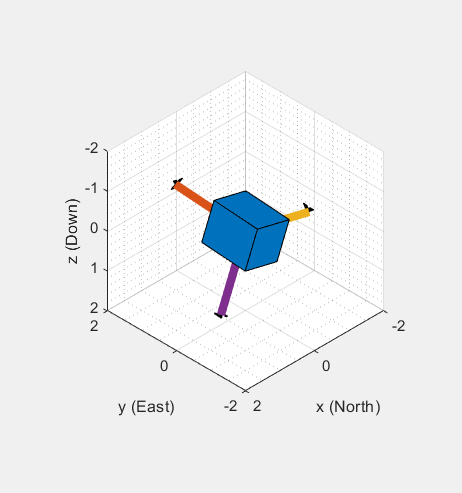

%% Clear IMU and Arduino Objects in  Workspace
clear
clear imu;
clear a; 

%Viewer Function 
%For viewer function to work: Local files HelperBox.m and
%HelperOrientationViewer.m must be in the workspace
viewer = HelperOrientationViewer;

%Create Arduino Object 
%(Arduino support package must be downloaded beforehand + Control Instrumentation Toolbox)  
a = arduino('COM9', 'Uno'); 

%Create IMU Sensor Object 
fs = 100; % Sample Rate in Hz 
imu = mpu6050(a,'SampleRate',fs,'OutputFormat','matrix'); 

%Accelerometer-Gyroscope Fusion with Kalman filter 
FUSE = imufilter('SampleRate', fs);

%Declare arrays for acceleration, velocity and time 
accelTimeSeries = [];
gyroTimeSeries = [];
timeArray = []; %temporary array used to concatenate time series
timeSeries = []; %time series correlating to accel and gyro measruements

%Simulation and Animation 
stopTimer=10; 
ts = tic; 
samplesPerRead = 10; %this is the default sample read on the MPU6050

while(toc(ts) < stopTimer) 
    [accel,gyro] = read(imu); 
    % Align coordinates in accordance with NED convention 
    accel = [-accel(:,1), accel(:,2), accel(:,3)]; 
    gyro = [gyro(:,1), -gyro(:,2), -gyro(:,3)];
 
    for i=1:samplesPerRead
        %create time array of size samplesPerRead of ts values
        timeArray = [timeArray;toc(ts)];
    end
    
    %Collect readings into series
    accelTimeSeries = [accelTimeSeries;accel];
    gyroTimeSeries = [gyroTimeSeries;gyro];
    timeSeries =  [timeSeries; timeArray];
    timeArray = []; %make temporary array empty
    
    rotators = FUSE(accel,gyro); 
    for j = numel(rotators) 
      viewer(rotators(j));
    end 
end


%Acceleration time series format: [time Ax Ay Az]
accelTimeSeries = [timeSeries accelTimeSeries];
%Orientation time series format: [time Gx Gy Gz]
gyroTimeSeries = [timeSeries gyroTimeSeries];
